Load data file (struct 3D format) and get axes order

path = 'B5 b5 150um 4 A_struct_3D_desired_order_frequency_amplitude_offset';
data = load(path)

data = struct with fields:
    select_data_desired_order_3D: [1×1 struct]


varname = fieldnames(data);
data = data.(varname{1});
str_before_order = 'order_'; % input the string just before the first parameter
order = MFIA_get_order_from_path(path, str_before_order)

order = 1×3 cell array
    {'frequency'}    {'amplitude'}    {'offset'}


title = path(sum(find(path=='\', 1, 'last'))+1:sum(strfind(path, '_struct'))-1)

title = 'B5 b5 150um 4 A'

Select data to plot (leave empty to plot all data in 3D struct) and define plot aliases (from IA parametric model)

plt_select_data = {};
plt_select_data(:,end+1) = {'param0'; 'Resistance [ohm]'};
plt_select_data(:,end+1) = {'param1'; 'Capacitance [F]'};

Select plot range

range = {};
range(:,end+1) = {'frequency'; [1e4 inf]};
range(:,end+1) = {'amplitude'; [-inf inf]}; 
range(:,end+1) = {'offset'; [-inf inf]};

Define slice planes

slice_planes = {};
slice_planes(:,end+1) = {'frequency'; [100 10000 500e3]};
slice_planes(:,end+1) = {'amplitude'; []}; 
slice_planes(:,end+1) = {'offset'; [-0.5]};

Add plot formatting commands

plt_cmds = {};
% plt_cmds{end+1} = 'grid on';
plt_cmds{end+1} = 'colorbar(''eastoutside'')';
plt_log_freq = true; % true for log plot frequency
if plt_log_freq
    disp('Frequency axis will be plotted in log scale')
    order{contains(order, 'frequency')} = 'log_frequency';
    range(:,contains(range(1,:), 'frequency')) = {'log_frequency'; log10(range{2,contains(range(1,:), 'frequency')})};
    slice_planes(:,contains(slice_planes(1,:), 'frequency')) = {'log_frequency'; log10(slice_planes{2,contains(slice_planes(1,:), 'frequency')})};
end

Frequency axis will be plotted in log scale


Plot slice planes of 3D data

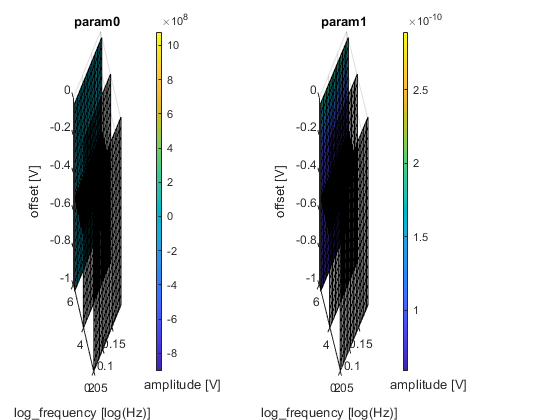

fn_plot_data3D(data, order, range, slice_planes, plt_select_data, plt_cmds);